# 4b

wordfile = export('hw56.mlx')

wordfile = 'C:\Users\jesse\Documents\MATLAB\Numerical Methods\Homework5.6\hw56.pdf'

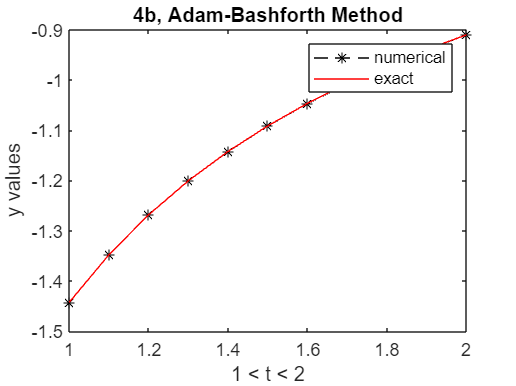

f = @(t, y)(y^2) / (1+t);
a = 1;
b = 2;

h = .1;
N = (b-a) / h; 
%step 1
t = a:h:b;
w = zeros(1, length(t));
t(1) = a;
w(1) = -1 / log(2);

%step 2
for i = 1:3
    %step 3
    k1 = f(t(i), w(i));
    k2 = f(t(i) + h/2, w(i) +h * k1/2);
    k3 = f(t(i) + h/2, w(i) + h*k2/2);
    k4 = f(t(i) + h, w(i) + h*k3);

    %step 4
    w(i+1) = w(i)+(h/6)*(k1+2*k2+2*k3+k4);
end


%step 6
for i = 4:N
    %step 7
   w(i+1) = w(i)+(h/24)*(55*f(t(i), w(i)) -...
       59*f(t(i-1), w(i-1))+37*f(t(i-2), w(i-2)) - 9*f(t(i-3), w(i-3)));
end

%actual solution
for i=1:N+1
    yexact(i) = -1 / log(t(i)+1);
end
figure
plot(t, w, 'k*--', 'DisplayName','numerical');
hold on
title('4b, Adam-Bashforth Method');
xlabel('1 < t < 2');
ylabel('y values');
plot(t, yexact, 'red', 'DisplayName','exact');
legend
hold off

## 2c

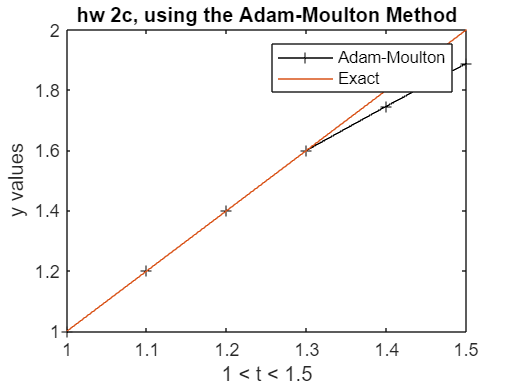

g = @(t, y)(y+1)/ t;
a1 = 1;
b1 = 1.5;

h = .1;
N1 = (b1-a1) / h;
%step 1
t1 = a1:h:b1;
w1 = zeros(1, length(t1));
t1(1) = a1;
w1(1) = 1;

%step 2
for i = 1:3
    %step 3
    k1 = g(t1(i), w1(i));
    k2 = g(t1(i) + h/2, w1(i) +h*k1/2);
    k3 = g(t1(i) + h/2, w1(i) + h*k2/2);
    k4 = g(t1(i) + h, w1(i) + h*k3);
    %step 4
    w1(i+1) = w1(i)+(h/6)*(k1+2*k2+2*k3+k4);
end
for i = 4:N1
    %step 7
   w1(i+1) = w1(i)+(h/12)*(5*g(t1(i+1), w1(i+1)) + 8*g(t1(i), w1(i)) - g(t1(i-1), w1(i-1)));
end
%actual solution
for i = 1:N1+1
    yexact2(i) = 2*t1(i) -1;
end
figure
plot(t1, w1, 'k+- ','DisplayName','Adam-Moulton');
hold on 
title('hw 2c, using the Adam-Moulton Method');
xlabel('1 < t < 1.5');
ylabel('y values');
plot(t1, yexact2, 'DisplayName', 'Exact');
legend
hold off

## 10(4b with algorithm 5.4)

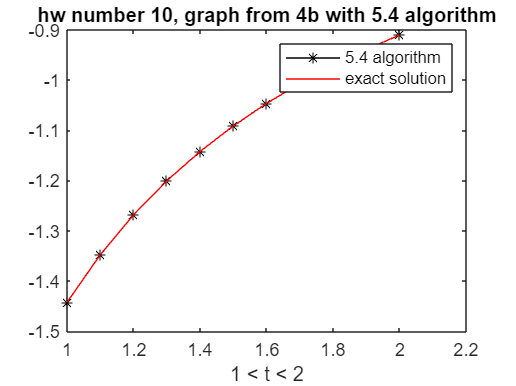

f1 = @(t, y)(y^2) / (1+t);
a2 = 1;
b2 = 2;

h = .1;
N2 = (b2-a2) / h; 
%step 1
t2 = a2:h:b2;
w2 = zeros(1, length(t2));
t2(1) = a2;
w2(1) = -1 / log(2);

%step 2
for i = 1:3
    %step 3
    t2(i+1) = t2(i) + h;
    k1 = h*f1(t2(i), w2(i));
    k2 = h*f1(t2(i) + h/2, w2(i) + k1/2);
    k3 = h*f1(t2(i) + h/2, w2(i) + k2/2);
    k4 = h*f1(t2(i) + h, w2(i) + k3);

    %step 4
    w2(i+1) = w2(i)+(k1+2*k2+2*k3+k4)/6;
    
end

for i=4:N2
    t2(i+1) = t2(i) + h;
    %predict w2(i+1)
    part1 = 55*f1(t2(i), w2(i)) - 59*f1(t2(i-1), w2(i-1))+37*f1(t2(i-2), w2(i-2));
    part2 = -9*f1(t2(i-3), w2(i-3));
    w0 = w2(i) + h*(part1 + part2) / 24;
    %correct w2(i+1)
    part1 = 9*f1(t2(i+1), w0)+19*f1(t2(i), w2(i))-5*f1(t2(i-1), w2(i-1))+f1(t2(i-2), w2(i-2));
    w2(i+1) = w2(i)+h*part1 / 24;
    
end
figure
plot(t2, w2, 'k*-', 'DisplayName','5.4 algorithm');
hold on
title('hw number 10, graph from 4b with 5.4 algorithm');
xlabel('1 < t < 2');
plot(t, yexact, 'r', 'DisplayName','exact solution');
legend
hold off